# **Controls for parameter tuning**

Linear classification

Holdout 50 or 80% --> community uses 80%

 --> maybe check a few cells

============

OBSERVATIONS

============

Analysis on MODULATION

==> WHAT ABOUT PEAK MAGNITUDE

==> WHAT NOT JUST THE PEAKS (full signal)

-  Encoder

-  EyeCam_Wheel --> check against encoder

-  L Forelimb

-  R Forelimb

-  Trunk (highest for 3-4 cells, so keep for now)

-  BodyCam LWhisker : The good one (behind, on black background)

- BodyCam RWhisker (on the whiskerpad, from the front + cuetip)

- Perioral

- trigger

- F0

**  shuffles (temporal and spatial permutation, separately, for all Conditions)

Excluded : 

- Laser

- BodyCam Eye --> meh

- Eycam whiskerpad (just check 09-12 exp 9-11 exp2 04-30-exp4

- eyecam Eye (check 09-04 exp2)

- NOT RT3D_MC BUT BASELINE F0 instead

============

PREDICTORS

============

* All ROIs

* Highest PHATE (+ and - for PHATEs 1-3)

* Perisomatic ROIS (6)

* 6 random ROIs 

* High PHATES GROUPS (6 ROIs of the PHATES 1->3 + and -)

% s = settings;
% s.matlab.editor.AllowFigureAnimation.PersonalValue = true;

# 1. Load experiment

% note : the experiment loaded here has been preprocessed for peak detection and
% rescaling. If this is not the case, you need to do it.
%load('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_final_new_zscored_compressed\2019-11-05_exp_3\2019-11-05_exp_3.mat')
%load('C:\Users\THE BEASTWO\Documents\MATLAB\arboreal_scans_final_new_zscored_compressed\2019-10-31_exp_1\2019-10-31_exp_1.mat')
load('C:\Users\Antoine.Valera\MATLAB\newextraction_dF_F0_zscored\2019-10-01_exp_1\2019-10-01_exp_1.mat')

# 2. Define the Analysis Settings

## Arboreal Scan settings

obj.detrend     = 0;% -1; %'auto'
obj.filter_win  = -1; % 
obj.rendering   = 0;
obj.process({'distance',50}); % will use obj.filter_win and obj.rendering
obj.get_dimensionality([],'phate','peaks_subtracted',[]);

## Machine Learning settings

use_classifier  = false;                % true or false

total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 3248 um
total dendritic length (-excluded branches) : 4254 um


Now detecting events with global pairwise correlation at least > 0.2 % 
    * Events detection is using PAIRWISE CORRELATION between all provided traces 
      Epochs of correlated changes of activity across a set % of the tree/pop will be considered as an event 


THR_FOR_GLOBAL = 0.5000

    * Events occuring in > 50% of the tree are considered global 
    * Maximal tree correlation is 82.7139%. A values < 100% indicates that either some sections belong to other neurons, or that the entire tree is never fully coactivated
      This function cannot distinguish between these two cases, but the value (max_corr_before_norm) will be set as the maximal possible correlation, and the globality index is proportional to this. This assumes that the entire tree CAN be correlated 
    * 312 events have been detected 
    * Peak times were extracted on the scaled avrage of all traces, but using the event times obtained with the global pairwise correlation. A jitter of 66.6667 ms was tolerated around the correated peak time 
    * 0events were of large enough amplitude to be detected on the averaged traces, but were not corrlated across the entire tree 


THR_FOR_CONNECTION = 0.2000

* Now detecting ROIs that are either,
      - so poorly correlated to the rest of the tree that they probably belong to another cell (or have no signal).
      - are member of batch_params.excluded_branches 
* Threshold for exclusion is  0.2 % 


RECOVERY_THR = 0.8000

ans = 15660×1 single column vector
   11.5640
    9.9140
    8.2271
    6.7825
    7.3537
    5.9792
    4.8149
    3.5854
    3.1047
    2.3662


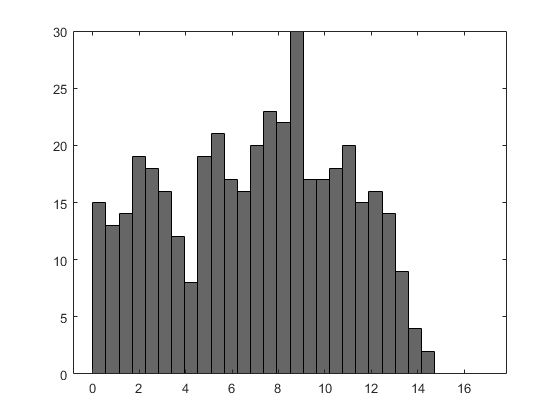

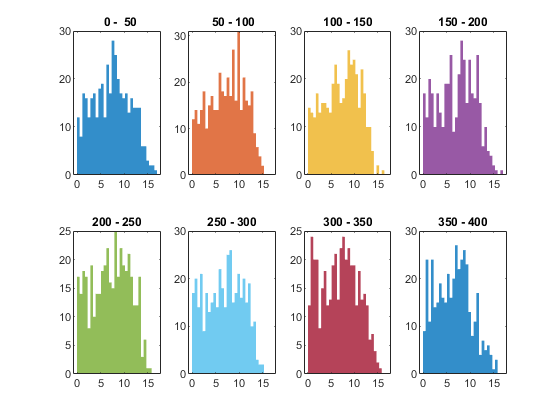

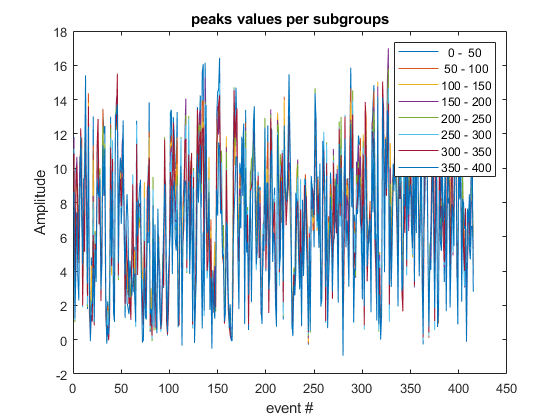

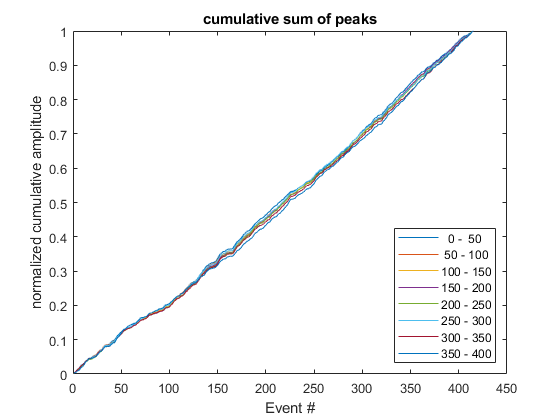

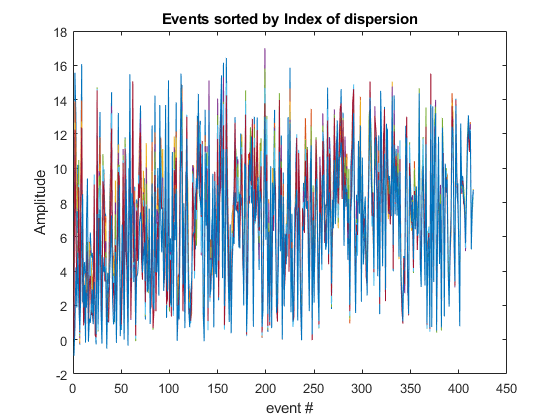

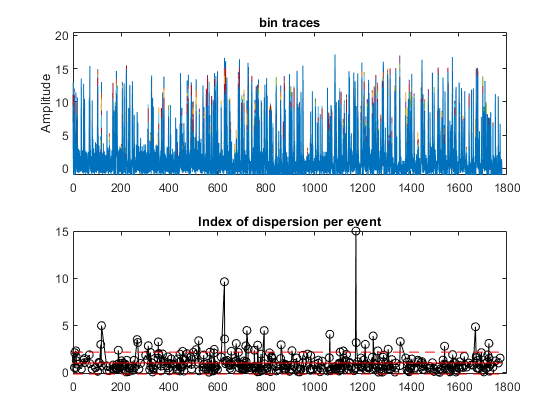

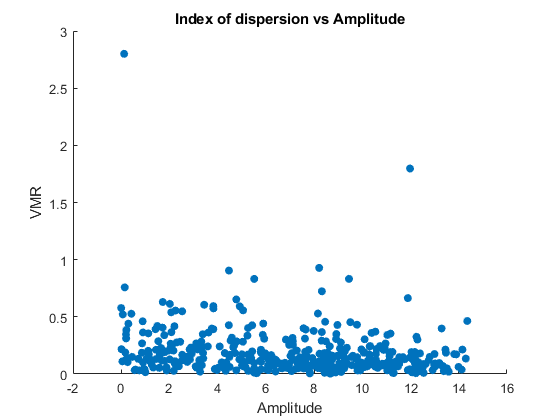

ans = 415×1 single column vector
    0.5142
    2.0978
    2.2969
    0.5354
    1.6583
    1.2512
    0.8654
    0.3745
    1.3077
    1.4799


Using current obj.cc_mode
Using current obj.cc_mode : groups_peaks


Doing PCA
PCA using random SVD
PCA took 0.018569 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 168
First iteration: k = 100
Number of samples below the threshold from 1st iter: 168
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.027079 seconds
Make kernel row stochastic
Running PHATE without landmarking
Finding optimal t using VNE
VNE optimal t = 30


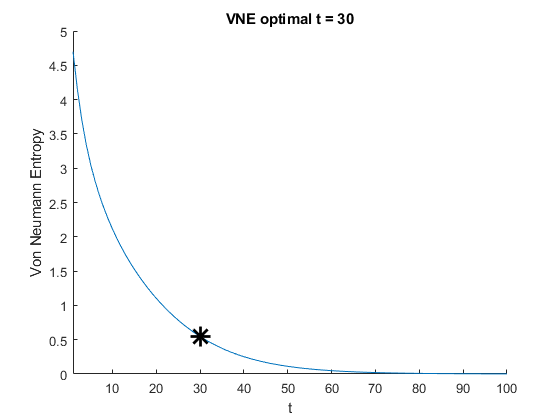

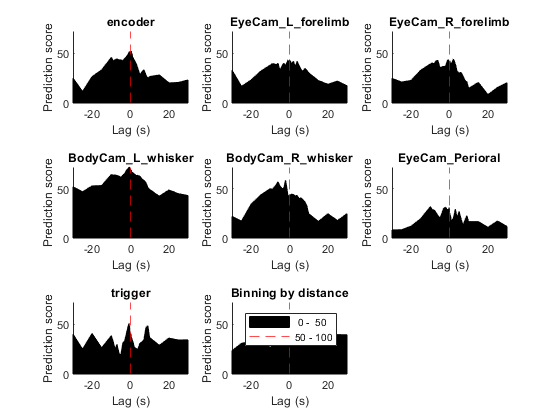

Diffusing operator
Diffusion took 0.003976 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.0045203 seconds
Doing classical MDS
CMDS took 0.0051388 seconds
Doing metric MDS:

                     Stress          Norm of         Norm of     Line Search
   Iteration       Criterion        Gradient           Step       Iterations
  ---------------------------------------------------------------------------
           0        0.946775       0.0154798
           1        0.324311      0.00823949         24.4522              10
           2        0.270835      0.00844981         10.7986               9
           3         0.18862       0.0126604         15.7153              12
           4        0.114426       0.0120072         6.75187              10
           5       0.0720226      0.00955701         4.44411               9
           6       0.0479077      0.00968811         2.67642              10
           7       0.0342415

method = 'dbscan'

rendering = logical
   0


MIN_CLUSTER_SIZE = 4

testing epsilon = 0.1
testing epsilon = 0.10475
testing epsilon = 0.10972
testing epsilon = 0.11492
testing epsilon = 0.12038
testing epsilon = 0.12609
testing epsilon = 0.13207
testing epsilon = 0.13834
testing epsilon = 0.1449
testing epsilon = 0.15178
testing epsilon = 0.15898
testing epsilon = 0.16652
testing epsilon = 0.17443
testing epsilon = 0.1827
testing epsilon = 0.19137
testing epsilon = 0.20045
testing epsilon = 0.20997
testing epsilon = 0.21993
testing epsilon = 0.23036
testing epsilon = 0.2413
testing epsilon = 0.25275
testing epsilon = 0.26474
testing epsilon = 0.2773
testing epsilon = 0.29046
testing epsilon = 0.30424
testing epsilon = 0.31868
testing epsilon = 0.3338
testing epsilon = 0.34964
testing epsilon = 0.36623
testing epsilon = 0.38361
testing epsilon = 0.40182
testing epsilon = 0.42088
testing epsilon = 0.44085
testing epsilon = 0.46177
testing epsilon = 0.48369
testing epsilon = 0.50664
testing epsilon = 0.53068
testing epsilon = 0.55586
testing epsilon = 0.5

MIN_GP = 4

obj = Using current obj.cc_mode : groups_peaks
  arboreal_scan_experiment with properties:

         extraction_method: 'median'
             source_folder: 'C:/Users/Antoine.Valera/MATLAB/newextraction_dF_F0_zscored/2019-10-01_exp_1/'
             update_folder: ''
      extracted_data_paths: {1×30 cell}
               need_update: [1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1 1]
            arboreal_scans: {1×30 cell}
                 timescale: [1×1 struct]
                      demo: 0
        auto_save_analysis: 1
         auto_save_figures: 0
                filter_win: [0 0]
               filter_type: 'gaussian'
              dim_red_type: 'pca'
                  peak_thr: 2
               bad_ROI_thr: 0.2000
                   cc_mode: 'groups_peaks'
                   detrend: 0
              is_detrended: 1
               is_rescaled: 1
            default_handle: @(x)load_several_e

total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-excluded branches) : 4254 um
total dendritic length (-exc

method          = 'linear';             % 'linear' or 'svm'    
variable_type   = 'peaks_subtracted';   % 'peak_subtracted' or any other set of conditions / timepoints

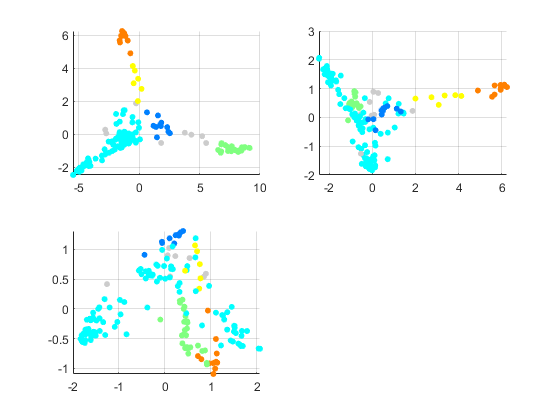

Doing PCA
PCA using random SVD
PCA took 0.0057022 seconds
using alpha decaying kernel
Computing alpha decay kernel:
Number of samples = 168
First iteration: k = 100
Number of samples below the threshold from 1st iter: 168
   Symmetrize affinities
   Done computing kernel
Computing kernel took 0.0056243 seconds
Make kernel row stochastic
Running PHATE without landmarking
Finding optimal t using VNE
VNE optimal t = 30


Diffusing operator
Diffusion took 0.002759 seconds
Computing potential distances
using -log(P) potential distance
Computing potential distance took 0.0017078 seconds
Doing classical MDS
CMDS took 0.0023053 seconds
Doing metric MDS:

                     Stress          Norm of         Norm of     Line Search
   Iteration       Criterion        Gradient           Step       Iterations
  ---------------------------------------------------------------------------
           0        0.946775       0.0154799
           1        0.324299      0.00823855         24.4526              10
           2        0.270831      0.00844895          10.798               9
           3        0.188597       0.0126618         15.7201              11
           4        0.114429       0.0120102          6.7501              10
           5        0.072011      0.00955792         4.44509               9
           6       0.0479008      0.00968869         2.67589              10
           7       0.0342366

behaviours      = {'encoder','EyeCam_L_forelimb','EyeCam_R_forelimb','BodyCam_L_whisker','BodyCam_R_whisker','EyeCam_Perioral','trigger','baseline'};

%behaviours      = {'encoder','BodyCam_L_whisker'}; 
N_iter          = 10;                   % N iterations
KFold           = 5; 
holdout         = 0;                    % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
rendering       = 1;                    % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.

# 3. Regular Behaviour Prediction

## On all ROIs

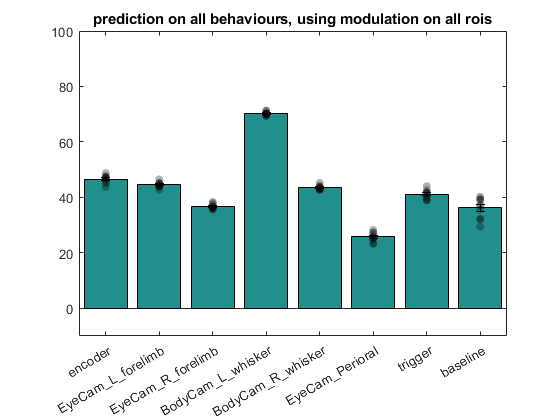

ROI_selection       = [];
result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on all ROIs'); % Bar chart title

## On ROIs with High Phate magnitude

N_phates        = 3;    % N dimensions
cutoff          = 0;    % 0 is just min and max
bidirectional   = true; % Postive AND negative magnitudes

try
    groups = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
catch
    obj.get_dimensionality([],'phate','peaks_subtracted',[]);
    groups = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);
end

% To study phates 1-3 up/down together and avg'd across ROIs (e.g. contents of cell array are avg'd prior to running ML) 
% e.g. if the cell 'cares' about avg. signals coming out of larger than our ROIs compartments
ROI_selection       = groups;
result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on High Phates'); % Bar chart title

## On ROIs identified by individual Phates


% to study phate 1,2 or 3 up or down in isolation (e.g. phate 1 up only) or clusters (e.g. DBSCAN)
% need to know what is in groups for this to be interpretable
N_phates        = 3;    % N dimensions
cutoff          = 5;    % 0 is just min and max
bidirectional   = true; % Postive AND negative magnitudes
groups          = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);

for jj = 1:numel(groups)
    groups{jj}
    result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                                 method         ,... % 'linear' or 'svm'
                                                 variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                 behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                 groups{jj}     ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                 N_iter         ,... % N iterations
                                                 false          ,... % if true, random groups are generated matching "ROI_selection" size
                                                 'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                 'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                 'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                 'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                 'kfold', KFold             ,...
                                                 'title', ['Prediction on all behaviours, using modulation on ROIs of group', num2str(jj)]); % Bar chart title
end


## On ROIs identified by clustering

obj.cluster_factors('dbscan',-5);
ROI_selection       = obj.dimensionality.clust_groups; 

result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on clusters of ROIs'); % Bar chart title


% %to study combos of phate groups (e.g. phate 1-3 up/up/up, phate 1-3 down/down/down, phate 1 up/down, phate 2 up/down, phate 3 up/down)
% prepare_test_groups    % this generates lists of ROIs defined by up/down phate cutoff 
% for jj = 1:numel(test_groups)
%     test_groups{jj}
% 
% results_high_phate = {}; 
% for iter = 1:N_iter
%     results_high_phate{iter} = predict_behaviours(obj, false, 'linear', variable_type, behaviours, test_groups{jj}, 'optimize_hyper', true, 'rendering', rendering, 'optimization_method', 'manual', 'holdout', holdout, 'kfold',KFold);
% end
% bar_chart(results_high_phate, 'beh_type');title('Prediction on all behaviours, using modulation on High Phates')
% end

## On perisomatic ROIs

ROI_selection       = num2cell(obj.ref.indices.somatic_ROIs); % Get perisomatic ROIs (i.e 1st ROI of each branch emerging from the soma OR lowest ROIS of apical dendrite when no soma.
result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on perisomatic ROIs'); % Bar chart title


# 4. Controls

## 4.1. Time Shuffling

% Using the entire dendritic tree on the encoder
ROI_selection       = [];
result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on all ROIs, but Ca2+ events are shuffled',... % Bar chart title
                                             'shuffling','events'); 

## 4.2. Spatial Shuffling

% Using the entire dendritic tree on the encoder
ROI_selection       = [];
result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction on all behaviours, using modulation on all ROIs, but Ca2+ events are shuffled',... % Bar chart title
                                             'shuffling','ROIs'); 


## 4.3. Trial Shuffling

% Using the entire dendritic tree on the baseline and encoder
trial_shuff_results = {}; 
shuffled_beh  = strcat(behaviours, '_shuffle');
shuffled_beh = reshape([behaviours; shuffled_beh],[],1)';
%shuffled_beh  = {'encoder','encoder_shuffle','EyeCam_L_forelimb','EyeCam_L_forelimb_shuffle','EyeCam_R_forelimb','EyeCam_R_forelimb_shuffle','BodyCam_L_whisker','BodyCam_L_whisker_shuffle','BodyCam_R_whisker','BodyCam_R_whisker_shuffle','EyeCam_Perioral','EyeCam_Perioral_shuffle','trigger','trigger_shuffle','baseline','baseline_shuffle'};
%shuffled_beh  = {'baseline','baseline_shuffle','encoder'}

%variable_type = 1:100:15000 % mimics the slow baseline drift measurement

% need to convert the time points t into amplitudes for valid ROIs, then
% feed this to variable_type
% below is just a first approx/ball park estimate:
% 
% tt = find(obj.get_tp_for_condition('peaks'))
% num_ev = numel(vertcat(obj.event.peak_time{:})); %could use this or several other of the obj.event outputs to get # of events
% rand_timepoints = sort(tt(randi(numel(tt),1,num_ev)))

result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                             method         ,... % 'linear' or 'svm'
                                             variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                             shuffled_beh   ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                             N_iter         ,... % N iterations
                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                             'kfold', KFold             ,...
                                             'title', 'Prediction selected behaviours with and without shuffling, using modulation on all ROIs') % Bar chart title


% figure();plot(obj.rescaled_traces(:,77));hold on;scatter(variable_type, obj.rescaled_traces(variable_type,77),'r','filled')


## 4.4 ROI Groups Shuffling

## On randomized groups of ROIs

for condition = {'highest_phate', 'strong_phate', 'clusters', 'all'}
    switch condition{1}
        case 'highest_phate'
            N_phates        = 3;    % N dimensions
            cutoff          = 0;    % 0 is just min and max
            bidirectional   = true; % Postive AND negative magnitudes
            ROI_selection   = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional);      
        case 'strong_phate'
            N_phates        = 3;    % N dimensions
            cutoff          = 5;    % 0 is just min and max
            bidirectional   = true; % Postive AND negative magnitudes
            ROI_selection   = get_high_phate_ROIs(obj, N_phates, cutoff, bidirectional); 
        case 'clusters'
            obj.cluster_factors('dbscan',-5);
            ROI_selection   = obj.dimensionality.clust_groups;        
        case 'all'
            ROI_selection   = [];        
    end

    result_linear       = predict_behaviours(obj,use_classifier ,... % true or false
                                                 method         ,... % 'linear' or 'svm'
                                                 variable_type  ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                 behaviours     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                 ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                 N_iter         ,... % N iterations
                                                 true           ,... % if true, random groups are generated matching "ROI_selection" size
                                                 'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                 'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                 'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                 'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                 'kfold', KFold             ,...
                                                 'title', ['Prediction on all behaviours, using modulation on randomized ',condition{1},' ROIs']); % Bar chart title
end

# 5. Introducing Time Lag

%% Extract behaours first to prevent doing it every time inside the for-loop
extracted_beh   = prepare_behaviour_data(obj, behaviours);

%% Identify relevant timpoints
events_tp       = find(obj.get_tp_for_condition('peaks'));

%% Get lags
sr              = 1/nanmedian(obj.timescale.sr);
ROI_selection   = [];
R               = {};
lag_list        = [fliplr(logspace(log10(0.1),log10(20),15))*-1,0, logspace(log10(0.1),log10(20),15)];
% lag_list      = [round(linspace(-10,0.1,15)),0, round(linspace(0.1,10,15))];
% lag_list      = [-200,-100,-50,-10,-5,-2,-1,-0.5,-0.2,-0.1,0,0.1,0.2,0.5,1,2,5,10,50,100,200];
lag_list        = unique(round(lag_list * sr))

lag_list =   -177  -121   -83   -57   -39   -27   -18   -13    -9    -6    -4    -3    -2    -1     0     1     2     3     4     6     9    13    18    27    39    57    83   121   177


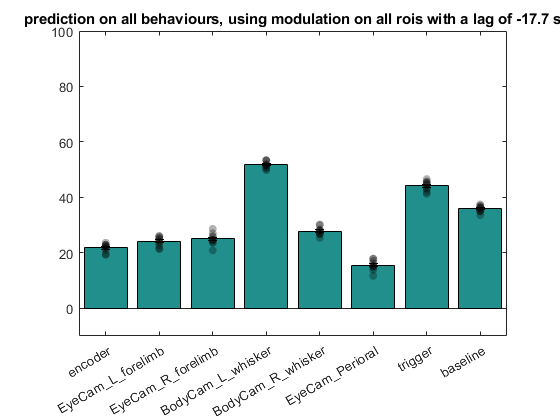

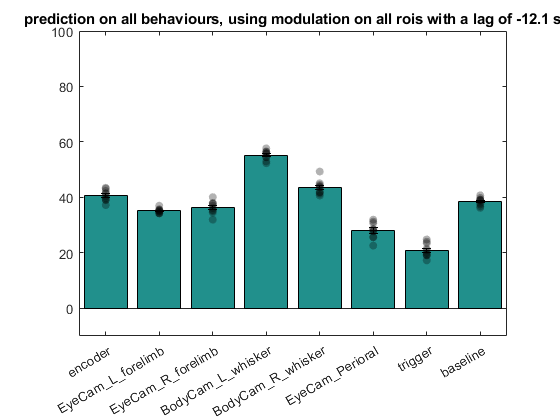

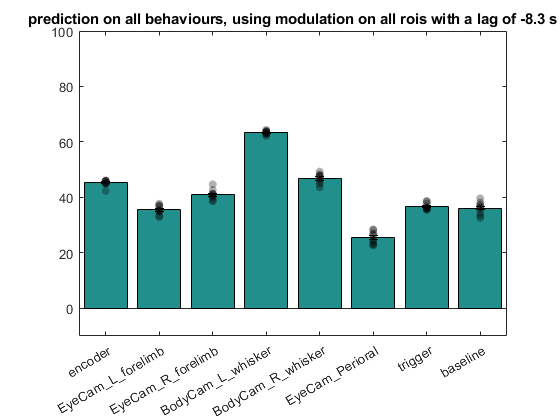

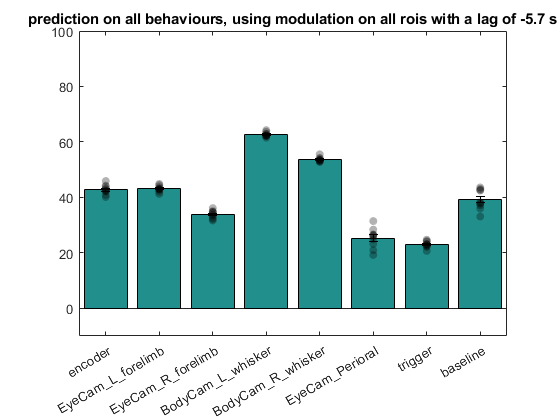

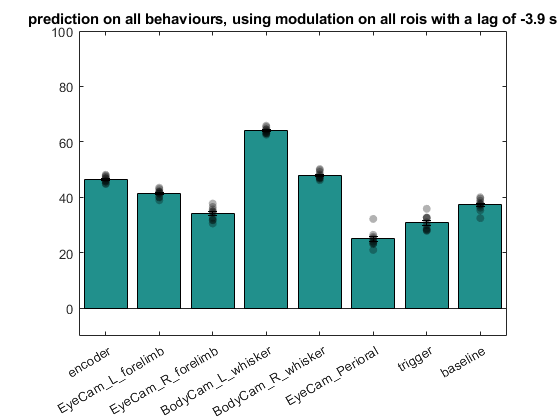

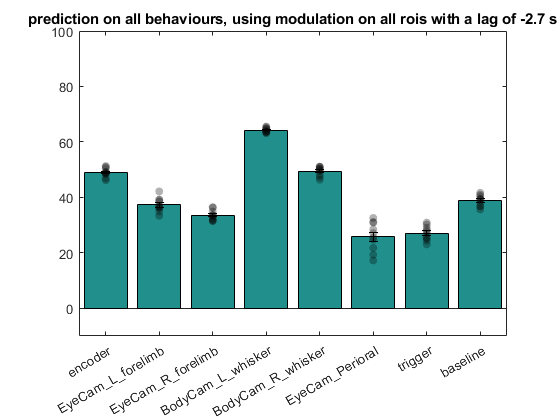

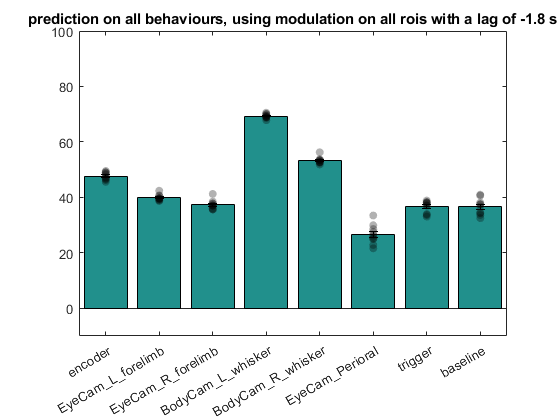

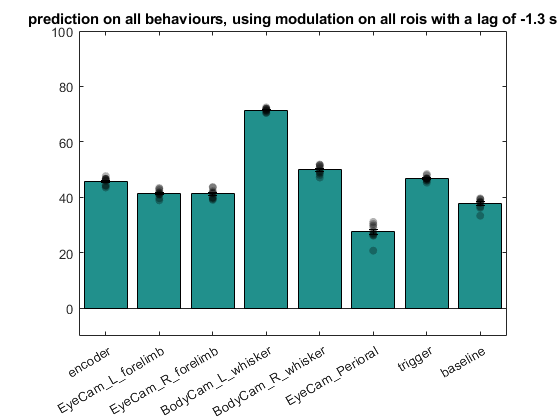


%% Run simulation for evry lag value
for lag_idx = 1:numel(lag_list) 
    lag = lag_list(lag_idx);
    [result_linear,~,~, R{lag_idx}]       = predict_behaviours(obj,use_classifier ,... % true or false
                                                             method         ,... % 'linear' or 'svm'
                                                             ['peaks_subtracted','_lag',num2str(lag)]       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                             extracted_beh  ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints. Use prepare_behaviour_data(obj, behaviours) before predcit_behaviours if you call the function several times 
                                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                             N_iter         ,... % N iterations
                                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                             'rendering', rendering     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                             'kfold', KFold             ,...
                                                             'title', ['Prediction on all behaviours, using modulation on all ROIs with a lag of ',num2str(lag/10),' s']); % Bar chart title
end

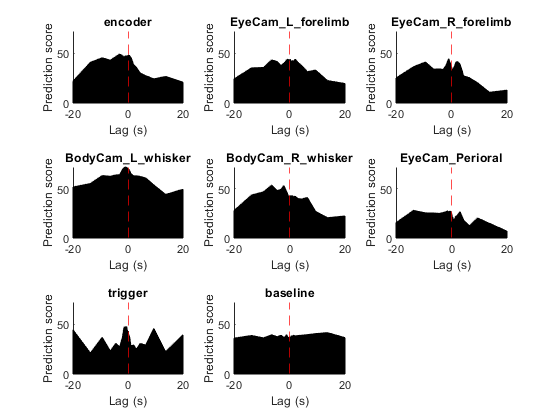


%% Plot lag results
a = cell2mat(R);x = lag_list/sr;
figure();tiledlayout('flow');
for beh = 1:numel(behaviours)
    axes(beh) = nexttile    ;  
    patch([x,fliplr(x)], [a(beh, :), zeros(size(a(beh, :)))], 'k');
    title(strrep(behaviours{beh},'_','\_'));xlabel('Lag (s)');ylabel('Prediction score');
    xline(0,'r--');
end
linkaxes(axes, 'xy')

# 6. Focusing on specific epochs

extracted_beh   = prepare_behaviour_data(obj, behaviours);

events_tp       = find(obj.get_tp_for_condition('peaks'));
sr              = 1/nanmedian(obj.timescale.sr);
ROI_selection   = [];
R               = {};

airpuff         = cellfun(@(x) any(contains(x, 'puff','IgnoreCase',true)), obj.logs); % puff, free, whisker
ok              = true(size(obj.t));
starts          = cumsum([1, obj.timescale.tp])

starts =            1         523        1045        1567        2089        2611        3133        3655        4177        4699        5221        5743        6265        6787        7309        7831        8353        8875        9397        9919       10441       10963       11485       12007       12529       13051       13573       14095       14617       15139       15661


for trial = 1:numel(airpuff)
    if airpuff(trial)
        ok(starts(trial):(starts(trial+1)-1)) = false;
    end    
end
ok = ~ok;

%lag_list        = [fliplr(logspace(log10(0.1),log10(20),15))*-1,0, logspace(log10(0.1),log10(20),15)];
lag_list        = unique([[0:0.1:1,1:10,10:5:30]*-1, [0:0.1:1,1:10,10:5:30]])

lag_list =   -30.0000  -25.0000  -20.0000  -15.0000  -10.0000   -9.0000   -8.0000   -7.0000   -6.0000   -5.0000   -4.0000   -3.0000   -2.0000   -1.0000   -0.9000   -0.8000   -0.7000   -0.6000   -0.5000   -0.4000   -0.3000   -0.2000   -0.1000         0    0.1000    0.2000    0.3000    0.4000    0.5000    0.6000    0.7000    0.8000    0.9000    1.0000    2.0000    3.0000    4.0000    5.0000    6.0000    7.0000    8.0000    9.0000   10.0000   15.0000   20.0000   25.0000   30.0000


% lag_list        = [fliplr(linspace(1,30,30))*-1,0, linspace(1,30,30)];

lag_list        = unique(round(lag_list * sr))

lag_list =   -265  -221  -177  -133   -88   -80   -71   -62   -53   -44   -35   -27   -18    -9    -8    -7    -6    -5    -4    -3    -2    -1     0     1     2     3     4     5     6     7     8     9    18    27    35    44    53    62    71    80    88   133   177   221   265


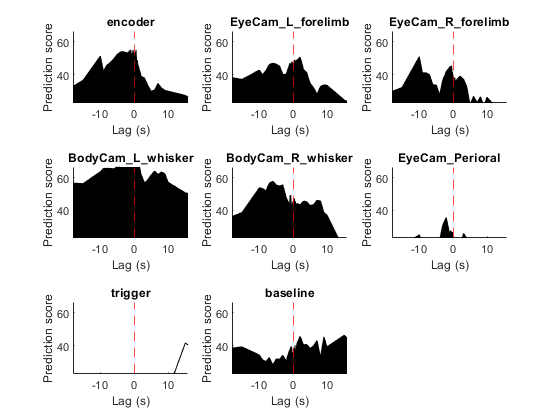

% beh_sub         = {'EyeCam_Perioral','BodyCam_L_whisker'}; % warning : You cannot test trigger by filtering aout all triggers


tic
for lag = 1:numel(lag_list)
    
    [result_linear,~,~, R{lag}]       = predict_behaviours(obj,use_classifier ,... % true or false
                                                             method         ,... % 'linear' or 'svm'
                                                             {['peaks_subtracted','_lag',num2str(lag_list(lag))], ok}       ,... % 'peak_subtracted' or any other set of conditions / timepoints
                                                             extracted_beh, ...%,'encoder','BodyCam_L_whisker'}     ,... % Cell array of behaviours. add "_shuffled" to a behaviours name to shuffle timepoints
                                                             ROI_selection  ,... % Cell array of ROI to use as predictor. One cell = one predictor. When multiple value per cell, values are avergaed. If passing a list, then all ROIs are used individually
                                                             1              ,... % N iterations
                                                             false          ,... % if true, random groups are generated matching "ROI_selection" size
                                                             'optimize_hyper', true     ,... % ML varargin ; if true, Lambda is optimized for each iteration
                                                             'rendering', false     ,... % If 0 no figure, if 1 summary plot is display per iteraton + averages, if 2, individual iteration data is displayed , if 3 hyperparameter optimization plot are displayed.
                                                             'optimization_method', 'manual',... % "manual" or "native". Native uses MATLAB baysian search parameter optimization for Lambda. Native generate a search grid and find Lambda with the best prediction score.. 
                                                             'holdout', holdout         ,... % percentage of data held out for final testing. If 0, we use KFoldLoss with custom Pearson coeff to estimate the score
                                                             'kfold', KFold             ,...
                                                             'title', ['Prediction on all behaviours, using modulation on all ROIs with a lag of ',num2str(lag_list(lag)/10),' s']); % Bar chart title
 
    

    a = cell2mat(R);x = lag_list(1:lag)/sr;
    figure(1);clf();
    tiledlayout('flow');
    for beh = 1:numel(extracted_beh.original_behaviour_list)
        axes(beh) = nexttile    ;
        %plot(x, a(beh, :)','o-');
        patch([x,fliplr(x)], [a(beh, :), zeros(size(a(beh, :)))], 'k')
        title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));xlabel('Lag (s)');ylabel('Prediction score');
        xline(0,'r--')
    end
    linkaxes(axes, 'xy')
    % figure();plot(x, a','o-');legend(behaviours);xlabel('Lag (s)');ylabel('Prediction score');xline(0)
        
end

toc

Elapsed time is 95.440611 seconds.


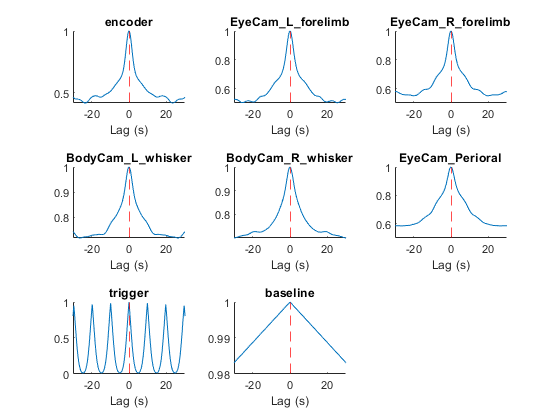



figure(2);clf();
tiledlayout('flow');
for beh = 1:size(extracted_beh.raw_behaviours, 1)
    axes(beh) = nexttile    ;
    title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));hold on
    plot(linspace(min(x), max(x), max(lag_list)*2+1), xcorr(extracted_beh.raw_behaviours(beh,:),max(lag_list),'normalized')); hold on
    xlabel('Lag (s)');xline(0,'r--')
end

% 
% a = cell2mat(R);x = lag_list/sr;
% figure(1);clf();
% tiledlayout('flow');
% for beh = 1:numel(extracted_beh.original_behaviour_list)
%     axes(beh) = nexttile    
%     %plot(x, a(beh, :)','o-');
%     patch([x,fliplr(x)], [a(beh, :), zeros(size(a(beh, :)))], 'k')
%     title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));xlabel('Lag (s)');ylabel('Prediction score');
%     xline(0,'r--')
% end
% linkaxes(axes, 'xy')
% % figure();plot(x, a','o-');legend(behaviours);xlabel('Lag (s)');ylabel('Prediction score');xline(0)


for sm = [0,1,10]
    extracted_beh   = prepare_behaviour_data(obj, behaviours,true, sm);
    figure();clf();
    tiledlayout('flow');
    for beh = 1:size(extracted_beh.raw_behaviours, 1)
        axes(beh) = nexttile    ;
        title(strrep(extracted_beh.original_behaviour_list{beh},'_','\_'));hold on
        plot(linspace(min(x), max(x), max(lag_list)*2+1), xcorr(extracted_beh.raw_behaviours(beh,:),max(lag_list),'normalized')); hold on
        xlabel('Lag (s)');xline(0,'r--')
    end
end

for beh = behaviours
%beh = 'L_forelimb';
    raw_beh = get_behaviours(obj, beh{1}, false, true, true, false);
    raw_beh = raw_beh{1};
    test = cellfun(@(x) x.value, raw_beh, 'uni', false);
    test = vertcat(test{:});
    test(isnan(test)) = 0;
    figure();plot(xcorr(vertcat(test), 150));title(beh{1})
end

5. Control based on the baseline behaviour

- h-word

- test if Ca is dirtributed normally (it should be, almost)

% run some (n = 16) key controls (e.g. do ML fo all ROIs with peaks_subtracted, raw_peaks, raw, raw_queit, quiet_subtracted
% plus a few shuffles where most relevant)

v = obj.rescaled_traces(obj.get_tp_for_condition('peaks'), :);
figure();hist(v(:),100);title('distribution of rescaled events amplitude (all ROIs)')
figure();hist(reshape((v - obj.global_median_rescaled(obj.get_tp_for_condition('peaks'))),[],1),100);title('distribution of median subtracted rescaled events amplitude (all ROIs)')



% plot_prediction(out{1}.calcium, out{1}.bin_beh{1}, out{1}.peak_tp{1}, out{1}.train_range{1}, out{1}.prediction{1}, out{1}.full_beh{1} , out{1}.beh_type{1}, out{1}.score{1});
